# Modism Project 3 - 1A

Rowan Jansens and Anthony Costarelli

## Question

On November 24th, 2021, a spacecraft named DART was launched. Its mission is to fly itself into an asteroid to test out whether such an impact could be a feasible method to redirect an earth-threating object (Talbert). 

In this model, we are **predicting** whether DART would have been able to redirect the Chicxulub impactor (the asteroid hypothesized to have led to the dinosaur extinction) and if so, how many years in advance would DART have needed to collide with the impactor to successfully deflect it away from Earth.

This is an interesting question because it can provide context into the scale of cosmic phenomena such as the Chicxulub impact in addition to what power humans have in influencing such an event. Additionally, it could highlight the areas of research that will be especially important if we are to redirect asteroid in the future.

## Method

### Visual Representation

We will begin by developing a 2d model of our system as depicted in the diagram below. The earth is placed statically at the origin while the Chicxulub impactor is free to move around according to Newtonian physics. DART will always impact the asteroid at a 90 degree angle to its current motion so as to maximize the potential to redirect the body.

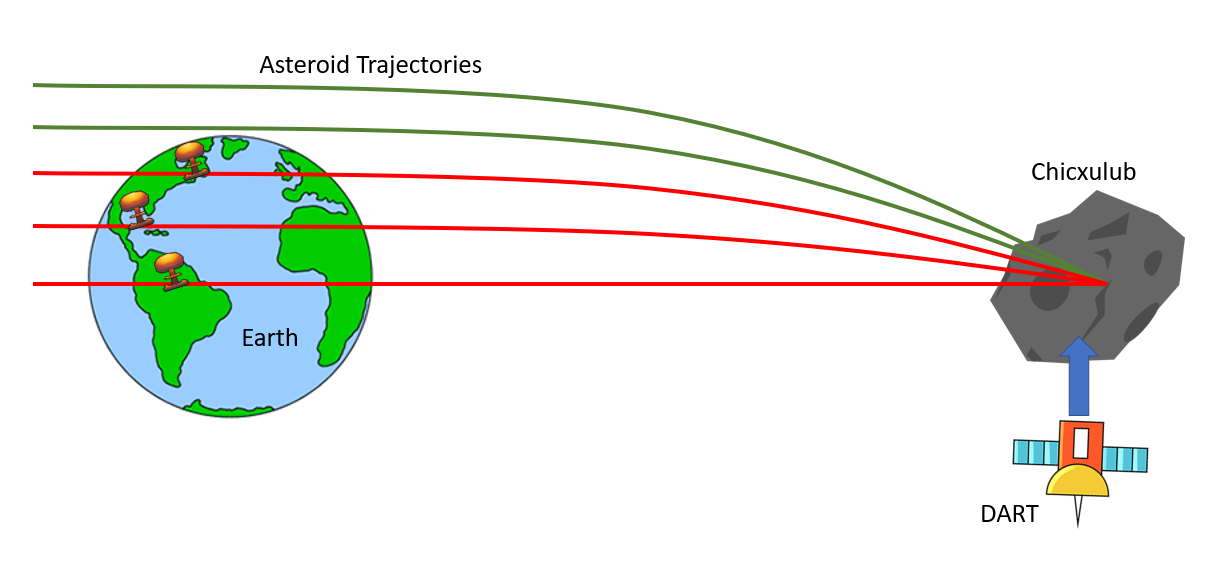 

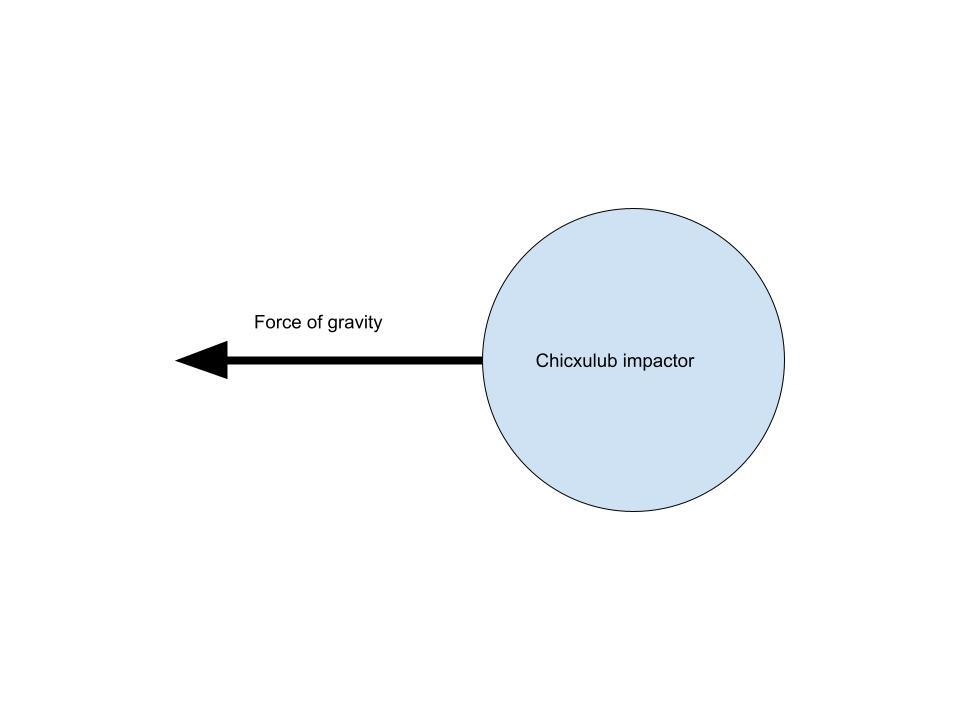

### Mathematical Representation

We will use the equation for standard gravitation to determine the motion of the asteroid.


$$\frac{d^2x}{dt^2} = -G\frac{m_{earth}}{x^2}\hat{r}$$


- Where $\hat{r}$ is a unit vector that points from the center of the asteroid to the origin (center of earth).

This equation can be decomposed into the following first order system:

- 
$$\frac{dv}{dt} = -G\frac{m_{earth}}{x^2} \hat{r}$$


- 
$$\frac{dx}{dt} = v$$


When the DART spacecraft collides with the asteroid, we will use conservation of momentum to find the new velocity of the asteroid at the time of collision. This momentum transfer is government by the following equations (NASA):

- 
$$P_{chic} + P_{DART} = P_{comb}$$


- 
$$m_{chic}v_{chic} + m_{DART}v_{DART} = m_{comb}v_{comb}$$


- 
$$v_{comb} = \frac{m_{chic}v_{chic} + m_{DART}v_{DART}}{m_{comb}}$$


### Computational Representation

In our initial model, we chose an arbitrary initial position and velocity for the Chicxulub impactor and then watched as it crashed directly into the Earth.  In this first iteration, we parameter-swept the distance from the Earth at which the DART collides with the impactor.

However, to make our model more realistic, we decided to simulate what the real Chicxulub trajectory might have looked like in our 2d system. We did this by setting the initial conditions of our model to the final conditions of the asteroid (speed, position, and inclination: values which have been extensive research and modeled by others (Collins)). Then we ran the model "backward" by multiplying the initial velocity by -1.  This left us with a simulated trajectory of what the Chicxulub trajectory might have looked like for as far back in time as we run the simulation. 

In this new iteration of our model, we parameter-sweep the “time before impact” at which the DART collides with the impactor. The position and velocity of the asteroid at that time is determined using the simulated trajectory. Since the trajectory of the real asteroid is essentially the focus of our model, we believe that this was an important iteration in helping us to generate meaningful results.

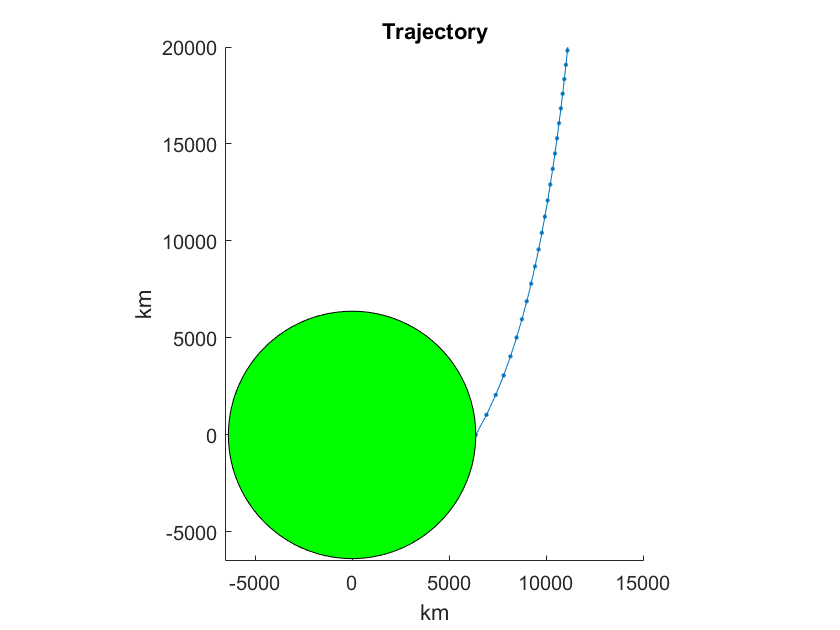

global year2sec
year2sec = 364.25 * 24 * 3600;

years = 0.01 * year2sec;
chic_data = chicxulub(years, 100);  % generate trajectory data for 0.01 years at 0.001 hour timesteps
plot_traj(chic_data); %plot the trajectory
axis([-6500 15000 -6500 20000])

This graph shows the first (or last) few datapoints from the reconstructed trajectory.

Initial testing revealed that even if the DART impacted Chicxulub was 1000 of years before earth impact, the altered trajectory would be insignificant. We used a crude calculation using the angle between the unperturbed trajectory and the trajectory after DART impact to hypothesize that the time required would be on the scale of hundreds of thousands of years. With this in mind, we decided to increase the DART mass significantly so that we would not need to model hundreds of thousands of years and could instead see results in just a few years. While this change does make our mode results non-realistic, it does not affect how the system behaves and allows for more efficient visualization of the system.

### Assumptions

There are several assumptions and simplifications that we are making in this model. One of the first assumption we made is that our asteroid is only affected by earth’s gravity. In reality, the asteroid will experience the gravity of the sun as well as other planets. All these objects would change the true trajectory of the asteroid. However, we did not think that including the effects of these “third” bodies would significantly change our results.

We are also assuming that the collision between DART and the asteroid is a 100% efficient momentum transfer. As the collision is happening in deep space, this seems to be a fair assumption. 

We also assumed that the mass of the asteroid is constant which is not realistic because the asteroid will lose considerable mass as it enters earth’s atmosphere. However, sources providing the asteroid's actual mass give a considerably large range, so the change in mass is likely within the uncertainty of the measurement.

Additionally, we are not modeling aerodynamic drag as the asteroid enters the atmosphere. However, these effects are likely insignificant considering how thin the atmosphere is at the scale and speed of Chicxulub.

### Verification

To verify our model, we simulated the Chicxulub trajectory using the “backward” simulation. Then we ran the simulation “forward” in time (without DART impacting it) and found that the asteroid fell back to earth in a nearly identical trajectory in addition to landing in the same location that it “took off” from. This proved that the “backward” calculation is a plausible way to calculate an approximate trajectory. This test also demonstrated that the ODE45 event function that we are using can correctly detect the asteroid colliding with the earth. 

We also looked at how the energy of the system changes before and after the DART collision. We found that the system loses energy, but this is the expected results consider that we did not add any constraints to this value in the model. If energy were modeled/constrained, the lost energy would have likely manifested itself in the sound and explosion associated with the impact.

### Validation

Although we struggled to get our model to work using realistic numbers for the mass and velocity of DART, we can still carry out validation to determine whether our model is on the right track. The DART spacecraft is estimated to change the velocity of its target asteroid (Dimorphos) by 0.4mm/s (Talbert). We simulated that DART would change the velocity of Chicxulub by around 5.8 e-7 mm/s. However, the mass of Chicxulub is much greater than the mass of the Dimorphos.  Taking this into account by multiplying each change in velocity by the mass of the body, we can compare the changes in momentum.


$$\Delta P_{chic} = 4.0 * 10^9$$



$$\Delta P_{dim} = 1.9 * 10^9$$


These two numbers are within an order of magnitude of each other, indicating that there may be some merit to our model.

## Results

The following figure shows a sweep of different collision times using the altered mass for DART. Green trajectories represent successful redirection while the red trajectory demonstrates trajectories that impact earth. The graph on the right also shows a more numerical output of the sweep, displaying earth impact across various times for the DART collision.  It also shows the minimum distance between earth and the altered trajectory.

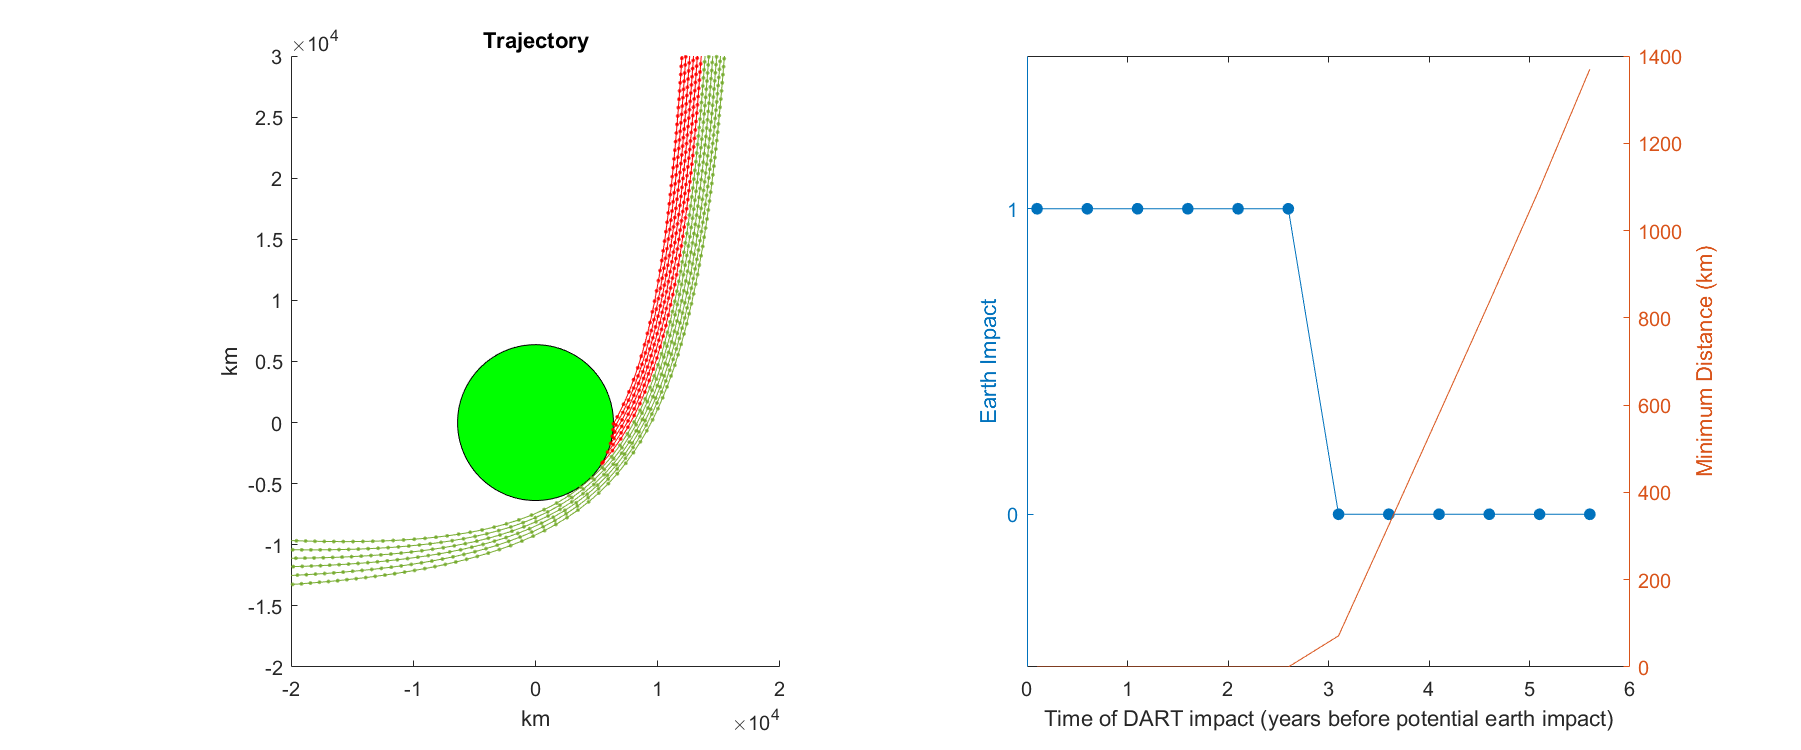

dt = 120;
chic_data = chicxulub(10*year2sec, dt); % calculate the trajectory of the impactor for 10 years @ dt = 120 seconds
sweep  %sweep through time before impact and plot trajectory

This shows that the DART (with mass set to 1e10kg) would have had to collide with the impactor at least 3 years in advance in order to deflect it enough to not hit the earth.

We also performed a "theoretical-lower-bound" simulation where DART has the mass of the International Space Station (the heaviest man-made spacecraft) and the velocity of Voyager I (the fastest man-made spacecraft). We used our rough calculation strategy mentioned earlier to estimate the time frame required and then ran this value through our model. 

We found that it would take an 80000 year lead time for a DART of this size and speed to be able to redirect the Chicxulub impactor.

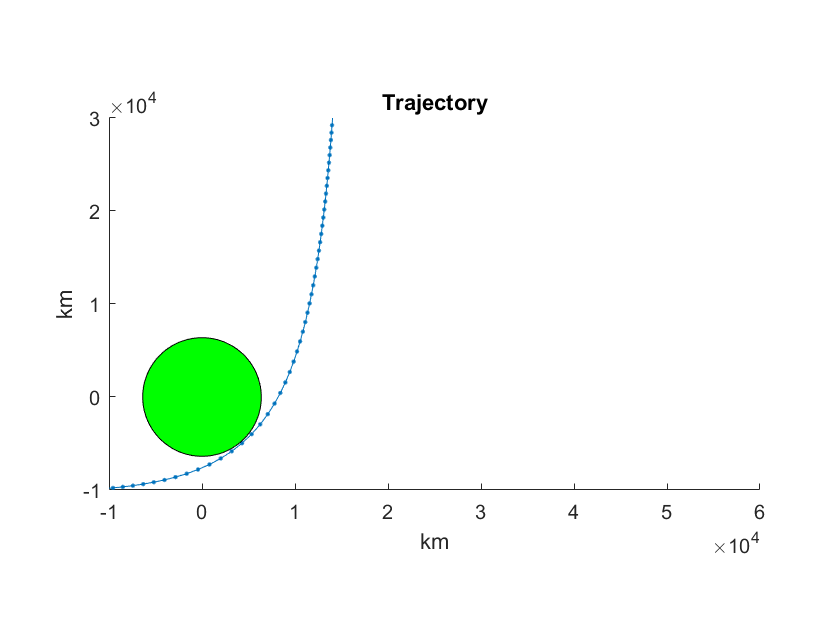

chic_data = chicxulub(80000 * year2sec, 3600 * 24 * 10); % calculate the trajectory of the impactor for 80000 years
[t, d] = trajectory1(80000 * year2sec, 3600 * 24 * 10, 120, chic_data);  %run the simulation
plot_traj([t d]) %plot

## Interpretation

The initial sweep results show that if we were able to launch an object that weighs 20 million times as much as the real DART spacecraft, we would only need to impact the Chicxulub asteroid three years in advance in order to redirect it safely away from earth.

For a more reasonable DART with the mass of the International Space Station (the heaviest man-made spacecraft) and the velocity of Voyager I (the fastest man-made spacecraft), we found that the DART collisions would need to happen 80,000 years in advance. This number can be considered our lower bound, and even though it is an unrealistic spacecraft, it still cannot deflect the impactor in any realistic amount of time. Additionally, these numbers do not consider the travel time required for DART to meet the asteroid which could require more than double the time. 

In order for this to be a feasible way to redirect asteroids in the future, humans will not only need to figure out how to launch huge masses into space and ludicrous speed, but they will also need to have the ability to identify the asteroid thousands of years in advance. Ultimately, it is not realistic for DART (or any other manmade satellite) to have been able to deflect the Chicxulub impactor and save the dinosaurs.

In the next iteration of our model, we could add a third body (the sun) as well as make some optimizations so that we can run our model with a realistic DART mass in a timely manner. We could also explore some of the other ideas for deflecting an asteroid such as by attaching a thruster to it.

## Sources

- Collins, G. S., et al. “A Steeply-Inclined Trajectory for the Chicxulub Impact.” *Nature News*, Nature Publishing Group, 26 May 2020, https://www.nature.com/articles/s41467-020-15269-x. 

- NASA. “Conservation of Momentum.” *NASA*, NASA, https://www.grc.nasa.gov/www/k-12/airplane/conmo.html. 

- Talbert, Tricia. “Double Asteroid Redirection Test (DART) Mission.” *NASA*, NASA, 30 June 2017, https://www.nasa.gov/planetarydefense/dart. 

- Wikipedia. “Chicxulub Crater.” *Wikipedia*, Wikimedia Foundation, 10 Dec. 2021, https://en.wikipedia.org/wiki/Chicxulub_crater. 